# 前半段，等同于homework1

clear;close, clc
fs=480e6;%系统采样速率
T=20e-6;
t = 1/fs:1/fs:T;
n=length(t);
f=(0:n/2)*(fs/n);%频率
f_low=12.5e6;f_hig=17.5e6;%上下边带
y=chirp(t,f_low,T,f_hig) ;%产生扫频信号

## 产生锯齿波信号

t_saw=1/fs:1/fs:T*10;
y_Saw=sawtooth(2*pi*1/T*t_saw);
y_Saw=y_Saw*5+6;

### 扫频信号与锯齿波相乘

y_A=y_Saw(1:9600).*y;
y_Afft=abs(fft(y_A));

### 进行60MHz采样

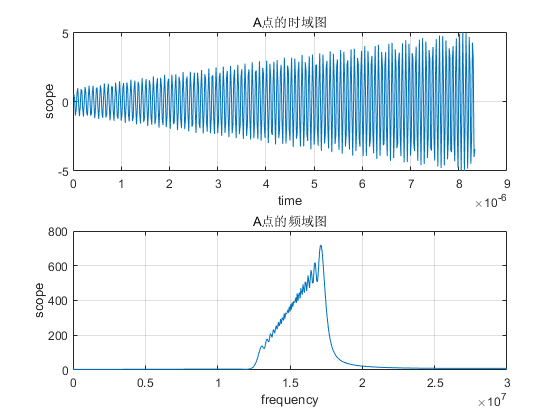

f_A=60e6;%60MHz的采样
t_A=1/f_A:1/f_A:T;%时间
n_A=length(t_A);
y_resamp=resample(y_A,1,8);
t_resamp=(1:length(y_resamp))*8/(fs);
figure
y_reFFt=abs(fft(y_resamp));
fs_resamp=(1:n_A/2)*(f_A/n_A);
subplot 211 
plot(t_resamp(1:500),y_resamp(1:500)),xlabel('time'),ylabel('scope'),title('A点的时域图'),grid on ;
subplot 212
plot(fs_resamp,y_reFFt(1:600)),xlabel('frequency'),ylabel('scope'),title('A点的频域图'), grid on;

# 多相结构

# B点进行多相滤波(此处为3路)

f_B=f_A/3;%进行抽取频率变化
t_B=1/f_B:1/f_B:T;%B 处的时间
n_B=length(t_B);
fs_B=(1:n_B/2)*(f_B/n_B);

###         采用自己编写函数，课本里面的多相滤波结构是在频域结构进行变化，但是要是编写函数在频域有点麻烦，所以我对其进行变换，将滤波器在时域进行考虑，对他的系数进行划分分为三段，此处设计的难点在于我设计的滤波器的系数一直不是3的倍数，导致结果一直不对，最终从文献的到需要对其进行补零，然后结果就正确了。以下是我的大致思路。

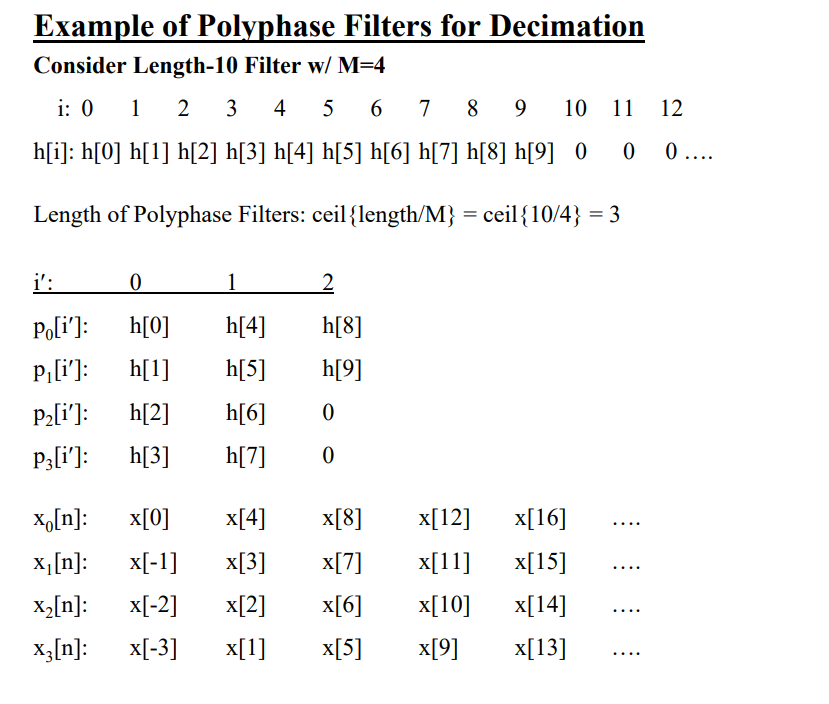

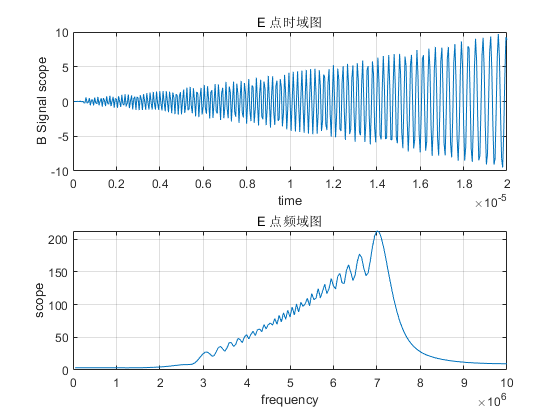

[a,b]=tf(bandpas_1);% 我们可以看出来这里a是滤波器的系数，但是他不是3的倍数因此对a进行补零
a=[a,0,0];% 得到滤波器的阶数
%Select polyphase signals
D0=y_resamp(1:3:end);
D1=y_resamp(3:3:end);
D2=y_resamp(2:3:end);
%Select polyphase signals
D_p0=a(1:3:end);
D_p1=a(2:3:end);
D_p2=a(3:3:end);
y_D=filter(D_p0,1,D0)+filter(D_p1,1,D1)+filter(D_p2,1,D2);%输出的时域值
y_Dfft=abs(fft(y_D));
figure
subplot 211
plot(t_B,y_D),xlabel('time'),ylabel('B Signal scope'),title('E 点时域图'), grid on ;
subplot 212
plot(fs_B,y_Dfft(201:400)),xlabel('frequency'),ylabel('scope'),title('E 点频域图'), grid on;

###         在此处利用多相结构对信号进行抽取，我们与homework1中的结果相比，如下图所示，可以看出时域频域的图都基本相同，但是还有一些不同，产生的愿意可能就是我的滤波器的结构不是他的整数倍产生的，我只是对其进行补零。但是总体结构也是相同的，并且此种方法也有人在使用。

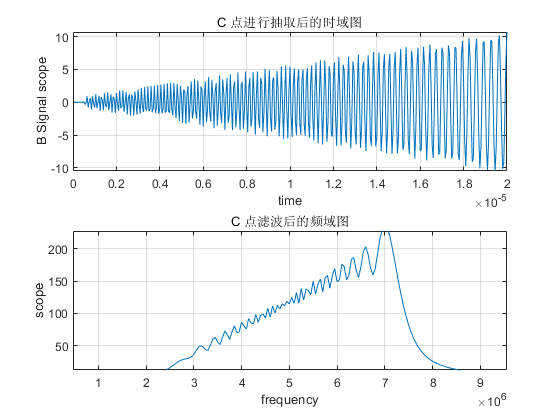

# 对F点进行8倍抽取

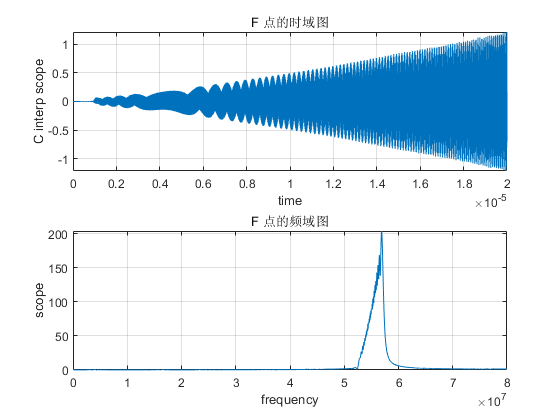

f_C=f_B*8;%进行抽取频率变化
t_C=1/f_C:1/f_C:T;%B 处的时间
n_C=length(t_C);
fs_C=(1:n_C/2)*(f_C/n_C);
[c,d]=tf(bandpass_2);%滤波器2
yushu=mod(length(c),8);
c=[c,zeros(1,8-(yushu))];%得到滤波器的阶数
F_p=reshape(c,8,[]);
for i=1:1:8
    y_f(i,:)=filter(F_p(i,:),1,y_D);
end
y_F=reshape(y_f,1,[]);
y_Ffft=abs(fft(y_F));
figure
subplot 211
plot(t_C,y_F),xlabel('time'),ylabel('C interp scope'),title('F 点的时域图'), grid on ;
subplot 212
plot(fs_C,y_Ffft(1:1600)),xlabel('frequency'),ylabel('scope'),title('F 点的频域图'), grid on;

##     结论：

- homework2 的设计难点在于多相滤波器，首先我碰到的问题在于设计的FIR滤波器阶数，滤波器的阶数最终是采用补零的方式。当然产生的是整数倍更好。

- 此外还有所采用的的函数filter，在FIR滤波器，filter函数和conv函数没有什么区别，一点在于他们所产生的的点数不同，假若使用IIR滤波器，这两个函数就不能通用了。只能采用filter函数。我具体的是参考网上的一个博客中的说法。

###     我的心得：调用某个函数需要对这个函数的原理搞清楚，不然会出现很多的bug。

最后也给出了采用matlab自带App中的多相滤波器结构，但是没有弄成功，原因在于补零结构那块，没法自动产生补零结构。

### 采用MATLAB带的App


% y=doFilter(B);
% yfft=abs(fft(y));
% figure
% subplot 211
% plot(t_B,y),xlabel('time'),ylabel('B Signal scope'),title('C 点进行抽取后的时域图'), grid on ;
% subplot 212
% plot(fs_B,y_Afft(201:400)),xlabel('frequency'),ylabel('scope'),title('C 点滤波后的频域图'), grid on;
% f_C=f_B*8;%进行抽取频率变化
% t_C=1/f_C:1/f_C:T;%B 处的时间
% n_C=length(t_C);
% fs_C=(1:n_C/2)*(f_C/n_C);
% 
% y_f=doFilter4(y);
% y_ff=y_f(end:-1:1,:);
% y_E=reshape(y_ff,1,[]);
% y_F_fft=abs(fft(y_E));
% figure
% subplot 211
% plot(t_C,y_E),xlabel('time'),ylabel('C interp scope'),title('D 点进行插值后的时域图'), grid on ;
% subplot 212
% plot(fs_C,y_F_fft(1:1600)),xlabel('frequency'),ylabel('scope'),title('D 点进行插值后的频域图'), grid on;
% B=reshape(y_resamp,3,[]);
% B1=B(1,:);%第一路采样信号
% B2=B(2,:);%第二路采样信号
% B3=B(3,:);%第三路采样信号
% [a,b]=tf(bandpas_1);
% h=reshape(a(1:(end-1)),3,[]);
% h1=h(1,:);%多相滤波器1
% h2=h(2,:);%多相滤波器2
% h3=h(3,:);
% y1=conv(B1,h1);
% y2=conv(B2,h2);
% y3=conv(B3,h3);
% y=y1+y2+y3;